# Spectrogram Project - Train from Scratch

The data used for this project was obtained from the [University of Iowa Electronic Music Studios](http://theremin.music.uiowa.edu/index.html).

The random seed is so the splitting between training, validation, and testing is consistent. If you are training on a GPU, your networks may not be the same if you train the same network multiple times.

rng(123)

## Load and split data

The images are stored in the folder `Spectrograms`. The data for each instrument is separated in subfolders, labelled by the folder name.

Split the data so that 80% of the images are used for training, 10% are used for validation, and the rest are used for testing. If changing the image size, make augmented image datastores.

ids=imageDatastore("Projects\MusicProject\Spectrograms","IncludeSubfolders",true,"LabelSource","foldernames");
[trig,vlig,tsig]=splitEachLabel(ids,0.8,0.1,0.1,"randomized");

trds=augmentedImageDatastore([100 100],trig);
vlds=augmentedImageDatastore([100 100], vlig);
tsds= augmentedImageDatastore([100 100], tsig);


## Series architecture from the documentation

You can find the example that uses this architecture in the documentation here: [Speech Recognition](https://www.mathworks.com/help/nnet/examples/deep-learning-speech-recognition.html#d119e1562)

The images are sized `[200 200 3]`.

lbls=14;
drp = 0.2;
layers = [
    imageInputLayer([100 100 3])

    convolution2dLayer(3,16,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,32,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,"Stride",2,"Padding",[0,1])

    dropoutLayer(drp)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(drp)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,"Stride",2,"Padding",[0,1])

    dropoutLayer(drp)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(drp)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer([1 13])

    fullyConnectedLayer(lbls)
    softmaxLayer
    classificationLayer];


## Train the network

Set the training options and train the network.

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |        1.56% |       22.62% |       5.6014 |       3.6272 |          0.0010 |


|       5 |          50 |       00:01:50 |       76.56% |       76.79% |       0.6757 |       0.7976 |          0.0010 |


|      10 |         100 |       00:03:33 |       91.41% |       88.10% |       0.2912 |       0.4813 |          0.0010 |


|      15 |         150 |       00:05:13 |       92.97% |       89.29% |       0.2334 |       0.4283 |          0.0001 |


|      20 |         200 |       00:06:46 |       92.97% |       89.88% |       0.2513 |       0.4040 |          0.0001 |


|      25 |         250 |       00:08:17 |       93.75% |       89.88% |       0.2181 |       0.4033 |      1.0000e-05 |


|      30 |         300 |       00:09:46 |       94.53% |       89.88% |       0.1914 |       0.4004 |      1.0000e-05 |


|======================================================================================================================|


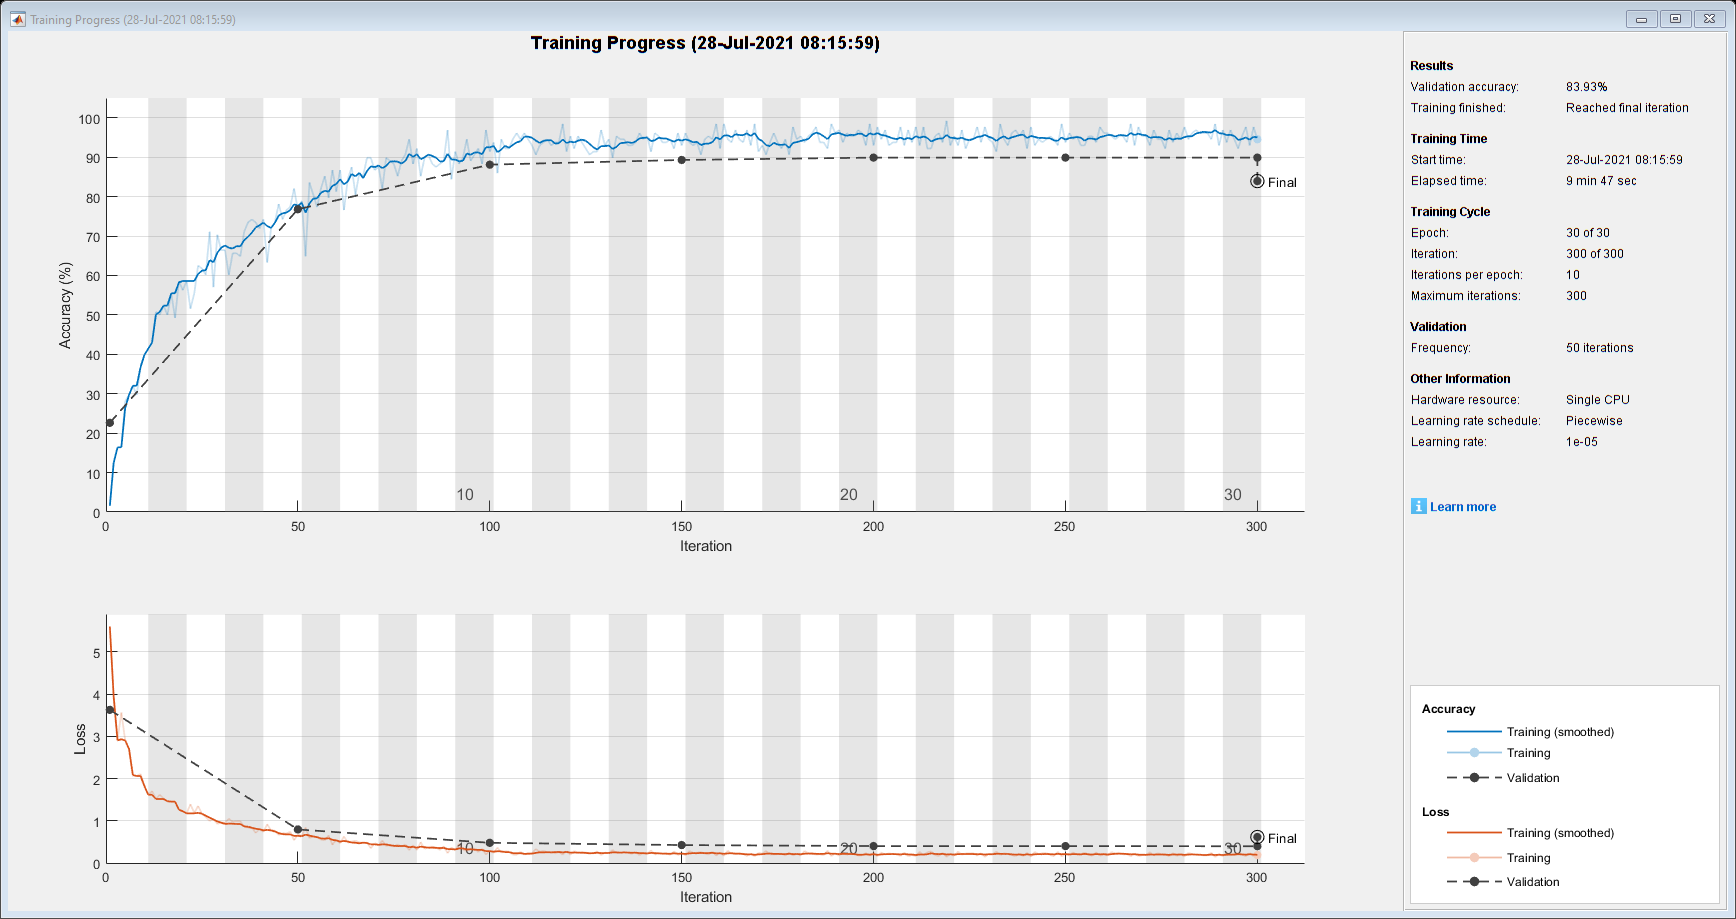

opt=trainingOptions("adam","Plots","training-progress","Verbose",true,"LearnRateSchedule","piecewise","LearnRateDropPeriod",10,"ValidationData",vlds);
scrnet= trainNetwork(trds,layers,opt);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:04 |        4.69% |       13.69% |       5.9819 |       4.5680 |          0.0100 |


|       5 |          50 |       00:01:36 |       54.69% |       54.17% |       1.2881 |       1.5699 |          0.0100 |


|      10 |         100 |       00:03:09 |       84.38% |       70.24% |       0.6160 |       1.0809 |          0.0100 |


|      15 |         150 |       00:04:42 |       89.84% |       79.76% |       0.4717 |       0.8539 |          0.0010 |


|      20 |         200 |       00:06:14 |       92.97% |       81.55% |       0.4105 |       0.7867 |          0.0010 |


|      25 |         250 |       00:07:54 |       86.72% |       81.55% |       0.4382 |       0.7763 |      1.0000e-04 |


|      30 |         300 |       00:09:36 |       87.50% |       81.55% |       0.4319 |       0.7670 |      1.0000e-04 |


|      35 |         350 |       00:11:07 |       90.63% |       81.55% |       0.4041 |       0.7662 |      1.0000e-05 |


|      40 |         400 |       00:12:40 |       90.63% |       81.55% |       0.4123 |       0.7659 |      1.0000e-05 |


|======================================================================================================================|


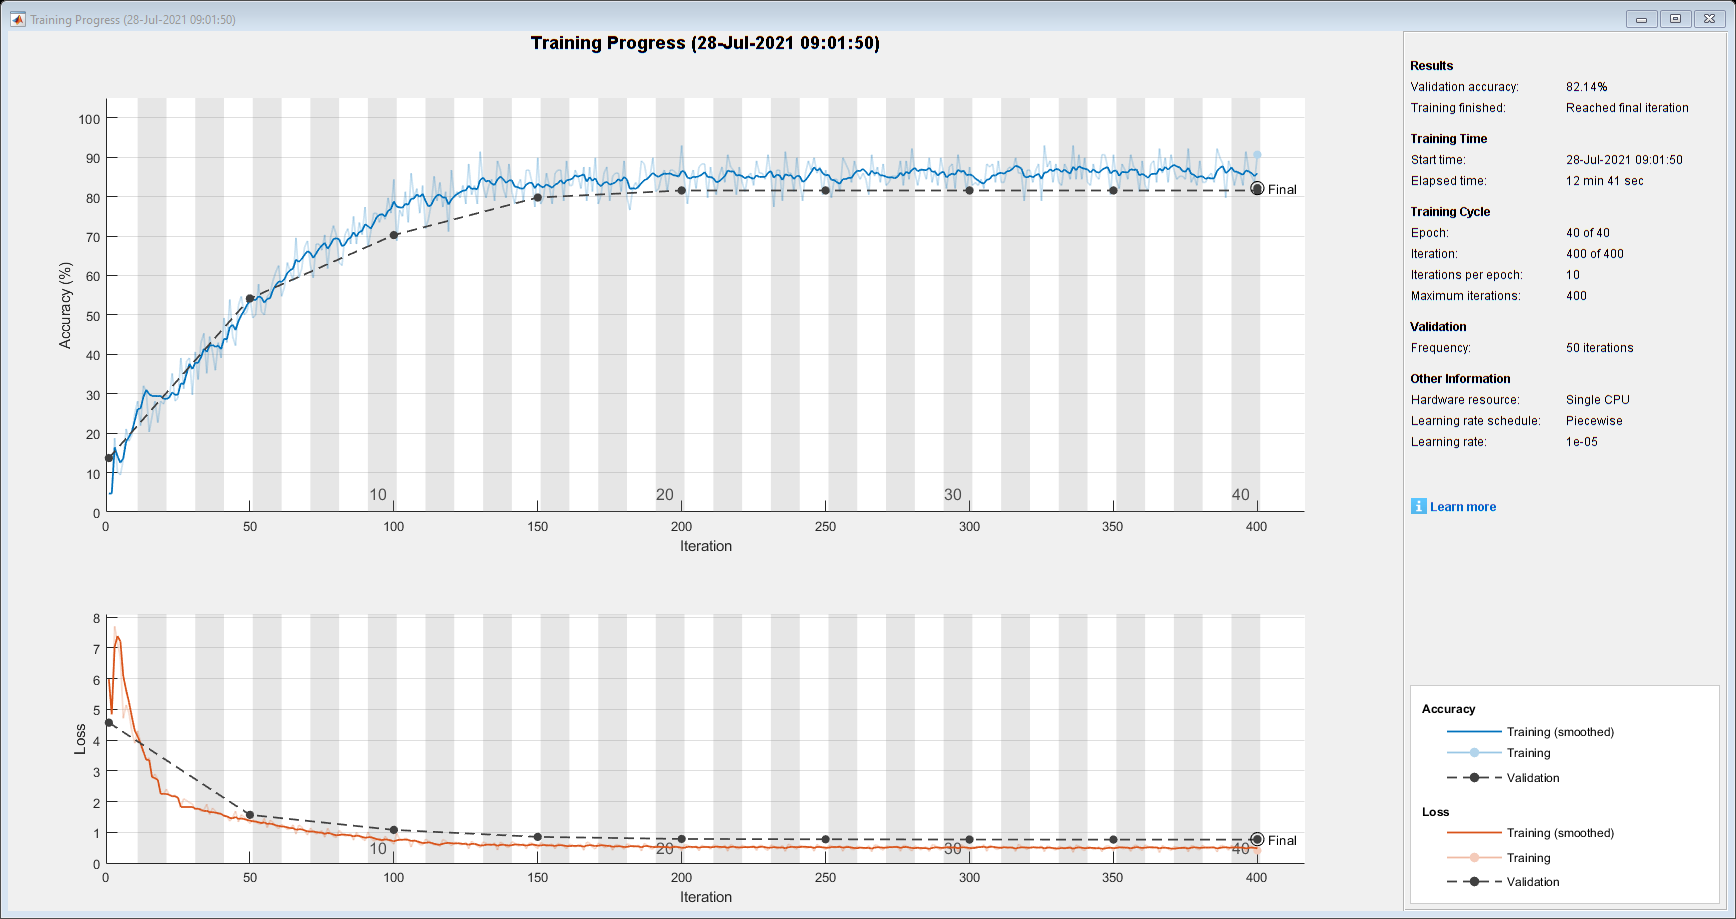

opt2=trainingOptions("adam","Plots","training-progress","Verbose",true,"LearnRateSchedule","piecewise","LearnRateDropPeriod",10,"ValidationData",vlds,"InitialLearnRate",0.01,"MaxEpochs",40);
scrnet2= trainNetwork(trds,layers,opt2);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:03 |        8.59% |       20.24% |       4.8994 |       3.2791 |          0.0010 |


|       5 |          50 |       00:01:35 |       81.25% |       80.95% |       0.5430 |       0.6594 |          0.0010 |


|      10 |         100 |       00:03:09 |       92.19% |       89.29% |       0.2668 |       0.3809 |          0.0010 |


|      15 |         150 |       00:04:43 |       96.09% |       92.26% |       0.1566 |       0.2846 |          0.0010 |


|      20 |         200 |       00:06:17 |       97.66% |       92.86% |       0.1069 |       0.2649 |          0.0001 |


|      25 |         250 |       00:07:50 |       99.22% |       93.45% |       0.1063 |       0.2558 |          0.0001 |


|      30 |         300 |       00:09:22 |       97.66% |       92.86% |       0.0923 |       0.2478 |          0.0001 |


|      35 |         350 |       00:10:56 |       98.44% |       93.45% |       0.0854 |       0.2486 |      1.0000e-05 |


|      40 |         400 |       00:12:33 |       98.44% |       92.86% |       0.0997 |       0.2471 |      1.0000e-05 |


|======================================================================================================================|


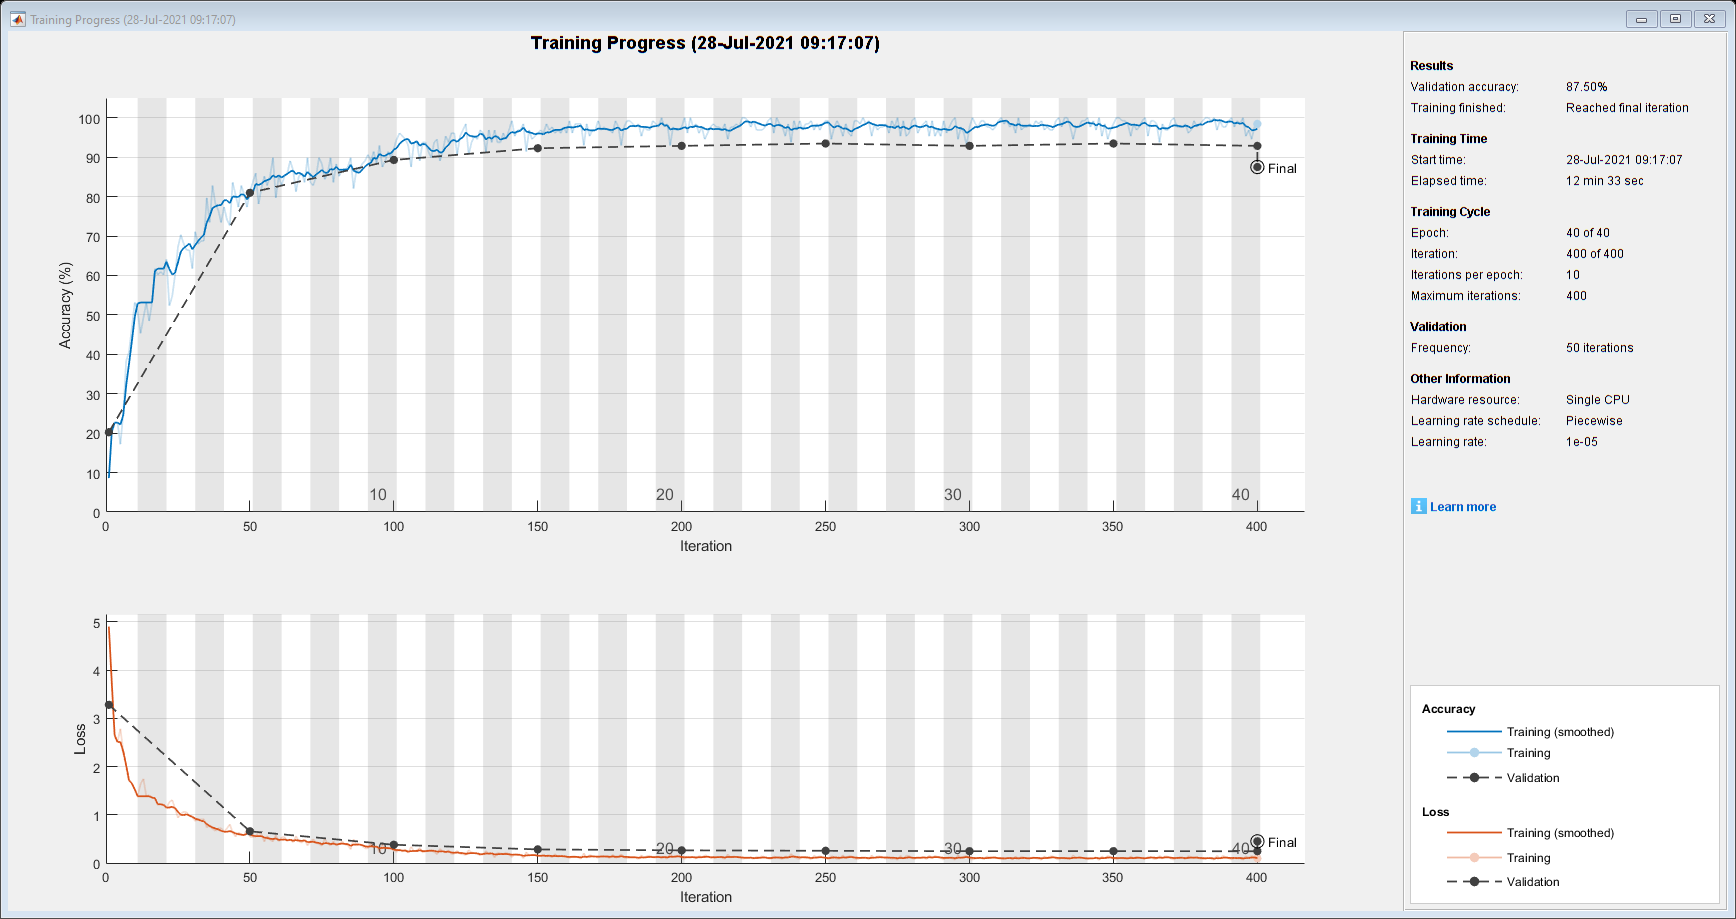

opt3=trainingOptions("adam","Plots","training-progress","Verbose",true,"LearnRateSchedule","piecewise","LearnRateDropPeriod",15,"ValidationData",vlds,"MaxEpochs",40);
scrnet3= trainNetwork(trds,layers,opt3);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:03 |        7.03% |       22.02% |       4.1875 |       3.0182 |          0.0010 |


|       5 |          50 |       00:01:34 |       84.38% |       77.98% |       0.5283 |       0.7625 |          0.0010 |


|      10 |         100 |       00:03:07 |       92.19% |       87.50% |       0.2535 |       0.3705 |          0.0010 |


|      15 |         150 |       00:04:40 |       99.22% |       89.29% |       0.0968 |       0.2751 |          0.0010 |


|      20 |         200 |       00:06:12 |       96.09% |       91.07% |       0.1210 |       0.2506 |          0.0001 |


|      25 |         250 |       00:07:46 |       98.44% |       91.67% |       0.0779 |       0.2387 |          0.0001 |


|      30 |         300 |       00:09:18 |       99.22% |       90.48% |       0.0861 |       0.2309 |          0.0001 |


|======================================================================================================================|


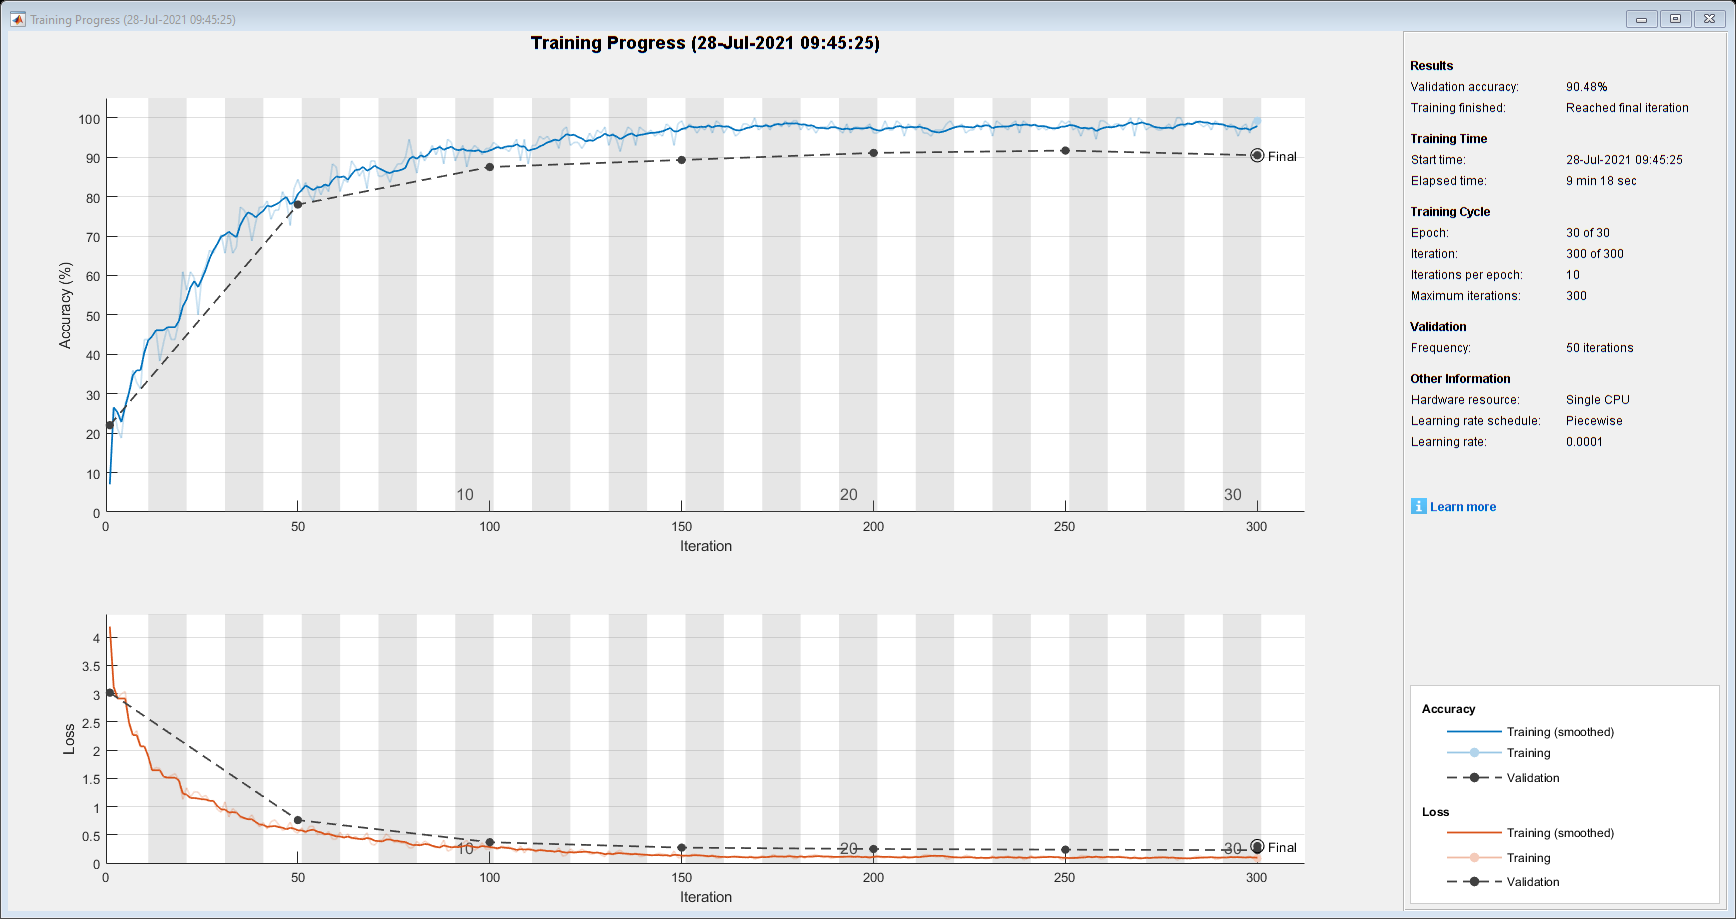

opt4=trainingOptions("adam","Plots","training-progress","Verbose",true,"LearnRateSchedule","piecewise","LearnRateDropPeriod",15,"ValidationData",vlds);
scrnet4= trainNetwork(trds,layers,opt4);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:03 |       16.41% |       14.88% |       3.9389 |       3.7883 |          0.0010 |


|       5 |          50 |       00:01:35 |       79.69% |       74.40% |       0.6547 |       0.7913 |          0.0010 |


|      10 |         100 |       00:03:08 |       92.97% |       87.50% |       0.2711 |       0.4260 |          0.0010 |


|      15 |         150 |       00:04:43 |       96.88% |       92.86% |       0.1349 |       0.2900 |          0.0010 |


|      20 |         200 |       00:06:16 |       96.09% |       92.86% |       0.1065 |       0.2761 |          0.0001 |


|      25 |         250 |       00:07:49 |       96.88% |       92.86% |       0.1080 |       0.2693 |          0.0001 |


|      30 |         300 |       00:09:24 |       96.09% |       92.86% |       0.1266 |       0.2615 |          0.0001 |


|      35 |         350 |       00:11:01 |       99.22% |       92.86% |       0.0967 |       0.2605 |      1.0000e-05 |


|      40 |         400 |       00:12:37 |      100.00% |       92.86% |       0.0770 |       0.2587 |      1.0000e-05 |


|      45 |         450 |       00:14:13 |       97.66% |       92.86% |       0.0847 |       0.2584 |      1.0000e-05 |


|      50 |         500 |       00:15:49 |       96.88% |       92.86% |       0.0983 |       0.2584 |      1.0000e-06 |


|======================================================================================================================|


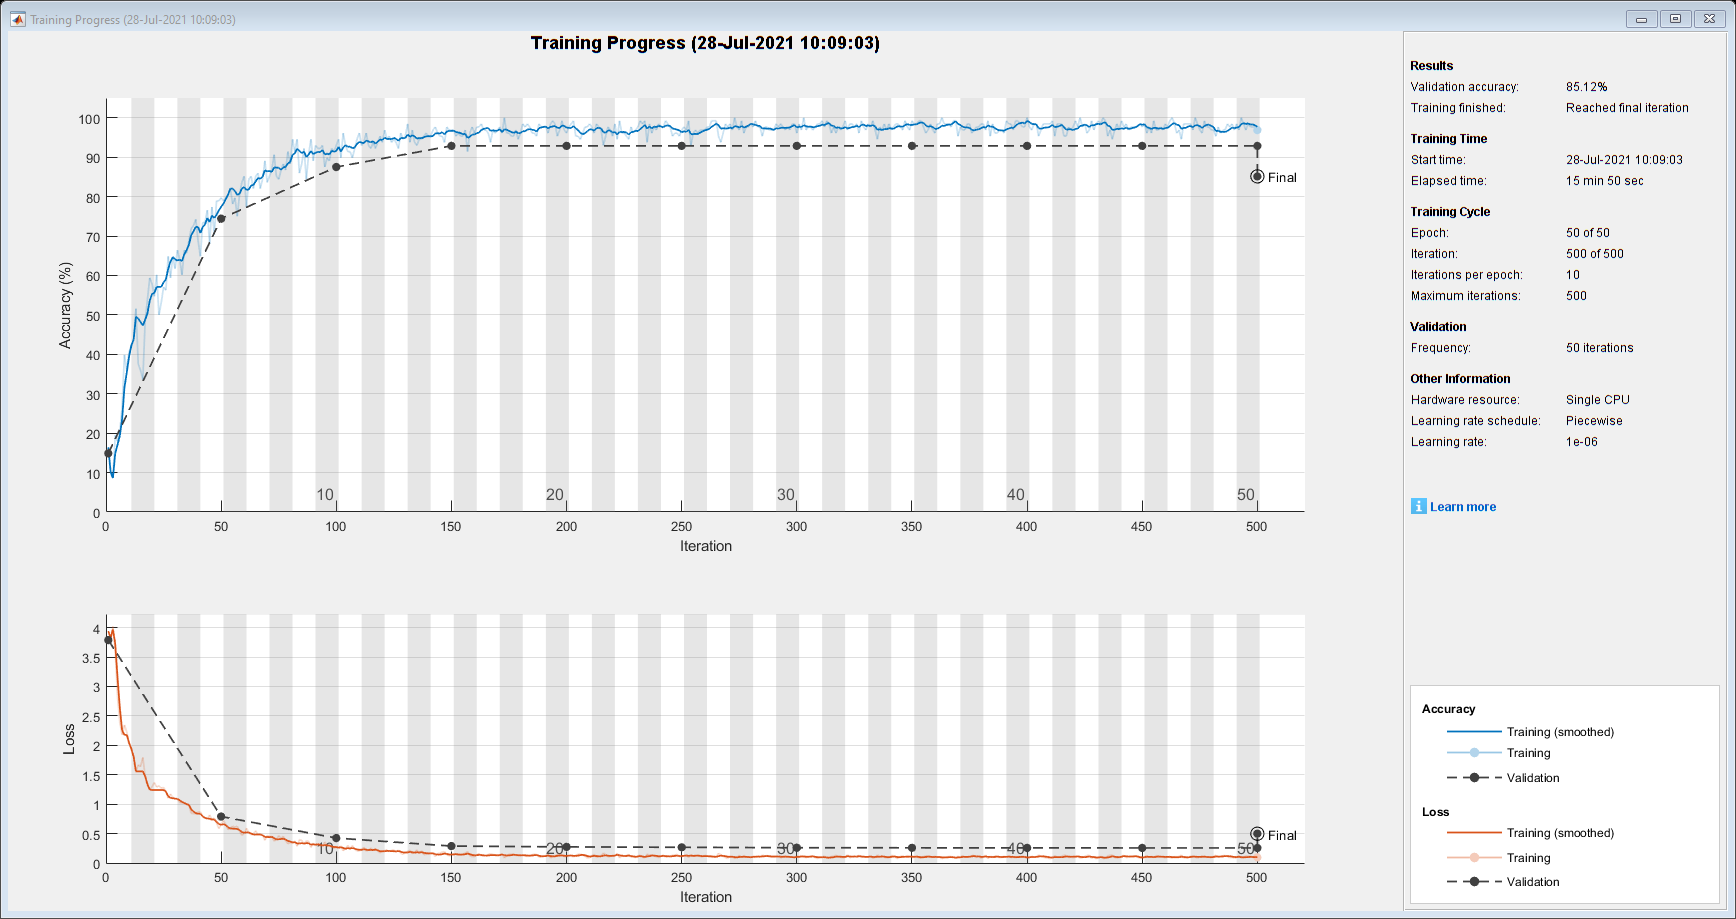

opt5=trainingOptions("adam","Plots","training-progress","Verbose",true,"LearnRateSchedule","piecewise","LearnRateDropPeriod",15,"ValidationData",vlds,"MaxEpochs",50);
scrnet5= trainNetwork(trds,layers,opt5);

## Evaluate network

Calculate the accuracy on the test dataset.

pred1 = classify(scrnet,tsds);
nnz(pred1 == tsig.Labels)/numel(tsig.Labels)

ans = 0.8204

Plot confusion matrix

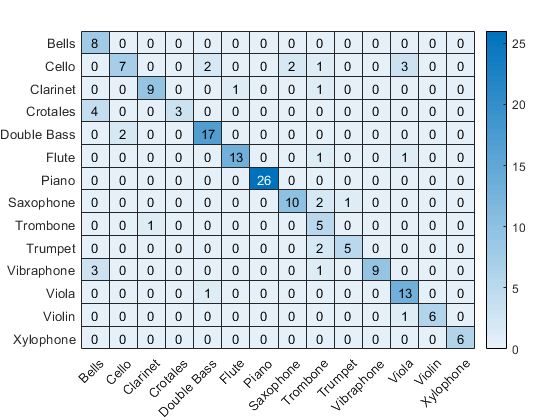

[cmap,clabel] = confusionmat(tsig.Labels,pred1);
heatmap(clabel,clabel,cmap)

pred5 = classify(scrnet5,tsds);
nnz(pred5 == tsig.Labels)/numel(tsig.Labels)

ans = 0.8563

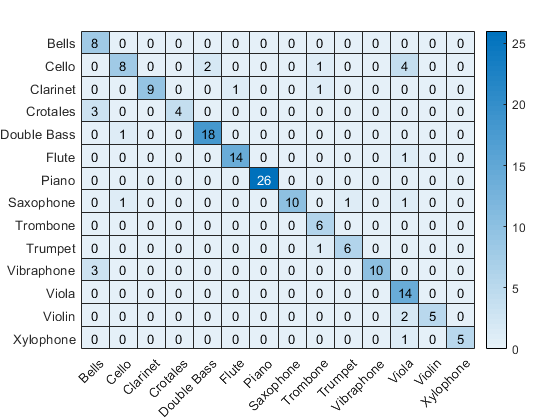

[cm,cl] = confusionmat(tsig.Labels,pred5);
heatmap(cl,cl,cm)